%Escribo las variables:
syms x Vector
%Pido el grado del espacio de polinomios y el número de polinomios:
grado=input('Escribe el grado del espacio de polinomios: ');
%Hallo el número de polinomios:
polinomios=grado+1;
%Pido la base dual al usuario:
    for i=1:(grado+1)
        for j=1:polinomios
            BaseOriginal(i, j) = input(['Escribe el termino de la base dual '...
                'correspondiente al i y j actual'...
                '(de 1,1 a 1,(grado+1) y así hasta (grado+1),(grado+1)): ']);
        end
    end
   while det(BaseOriginal) == 0
        %Si el determinante es 0, no existe la base dual
        disp('No existe la base dual');
        %Pido la base dual al usuario:
        for i=1:(grado+1)
        for j=1:polinomios
            BaseOriginal(i, j) = input(['Escribe el termino de la base dual '...
                'correspondiente al i y j actual'...
                '(de 1,1 a 1,(grado+1) y así hasta (grado+1),(grado+1)): ']);
        end
        end
   end

No existe la base dual


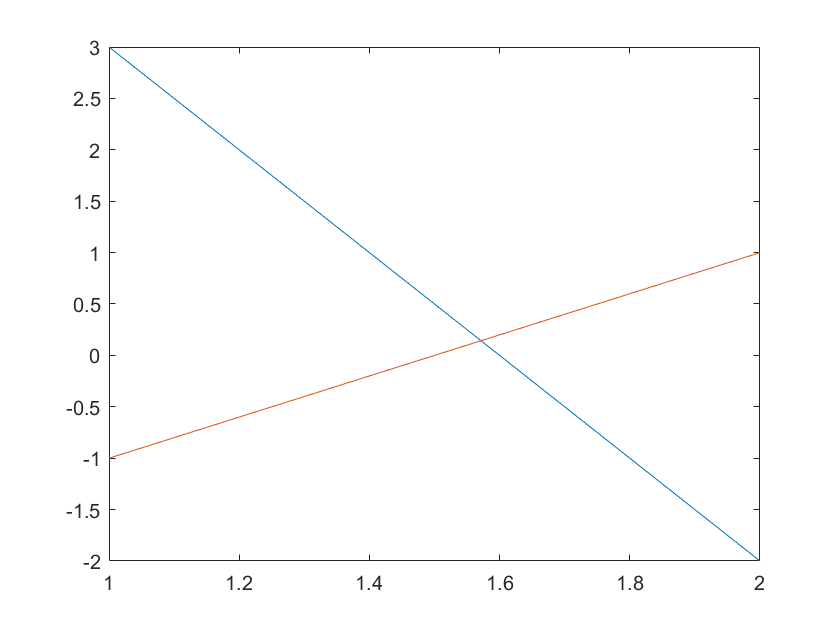

        %Calculo la base dual, es decir, la base inversa traspuesta:
    BaseDual = inv(BaseOriginal)';
    %Dibujo la base dual:
    plot(BaseDual);

    %Meto tantas x^n como tenga la matriz:
    for m=1:polinomios
        Vector(m)=x^(m-1);
    end
    %Calculo la base dual:
    Polinomioenbasedual=BaseDual*Vector';
    %Muestro la base dual:
    disp(Polinomioenbasedual);

$$\left(\begin{array}{c} 3-\bar{x}\\ \bar{x}-2 \end{array}\right)$$

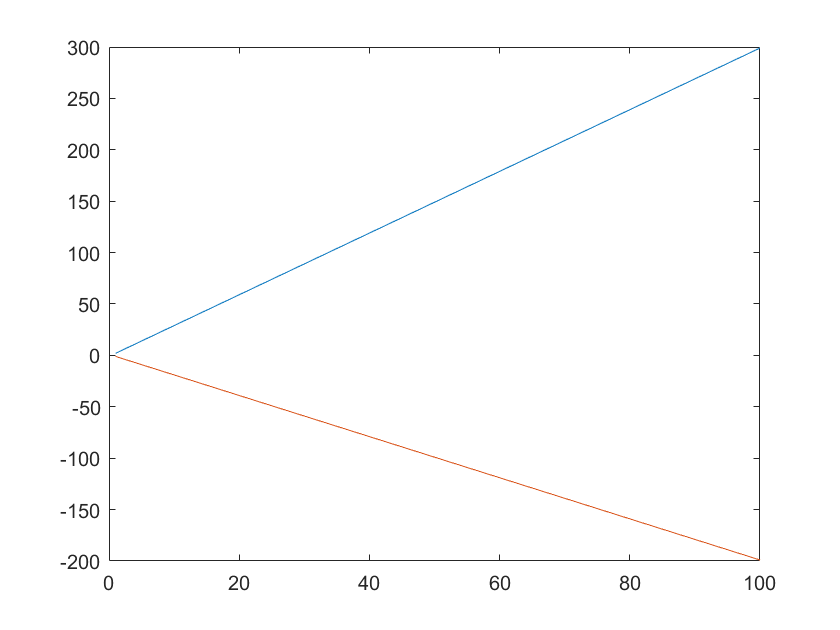

%Dibujo los polinomios de la base dual del intervalo 20 al 500 creciendo 10:
for i=1:polinomios
    %Escribo el dominio de la función.
    x=1:1:100;
    %Hallo el codominio de la función.
    y=polyval(BaseDual(i,:), x);
    plot(x,y);
    hold on
end